# Contextualization and analysis of human cell-type specific GEMs

## Author(s): Dana Luong**, Juan Sepulveda, Sara Mosavarpour, Renae Irving, Laboratory of Roger L Chang**, Albert Einstein College of Medicine.  

## Reviewer(s): .

## INTRODUCTION

This tutorial demonstrates an end-to-end workflow for contextualization and analysis of cell-specific or tissue-specific genome-scale metabolic models using the XomicsToModel${\;}^1$ pipeline. The XomicsToModel pipeline inputs multi-omic data and the generic human whole-body model Recon3DModel${\;}^2$ and outputs context-specific models. Following contextualization, flux sampling is performed, sampling convergence is evaluated, and basic differential flux analysis is used to begin prioritizing reactions and pathways for literature review and experimental validation.

## EQUIPMENT

Install MATLAB and then the COBRA Toolbox${\;}^3$ as described here: [https://opencobra.github.io/cobratoolbox/stable/installation.html.](https://opencobra.github.io/cobratoolbox/stable/installation.html.) Download the base Recon3D reconstruction from [https://www.vmh.life/#downloadview](https://www.vmh.life/#downloadview). This tutorial requires a solver suitable for solving linear (LP) and quadratic (QP) optimisation problems, e.g., mosek, gurobi, ibm_cplex, etc. This tutorial requires the Statistics and Machine Learning, Econometrics, Bioinformatics Toolboxes in MATLAB. 

## PROCEDURE

Initialize COBRA Toolbox and set an appropriate solver.

% TODO: set this filepath to cobratoolbox on your computer
cd /Users/dluong/Documents/MATLAB/cobratoolbox;
initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2025
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.39.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)...git submodule update --init --recursive --depth 1: Interrupt


changeCobraSolver('gurobi', 'all');

### 1. Define filepaths

Update these filepaths to ensure that inputs and outputs are read and saved as expected.

% TODO: Update this filepath to where you have this tutorial saved on your
% computer
WORKING_DIR = '/Users/dluong/Documents/fork-COBRA.tutorials/dataIntegration/XomicsToModel';
cd(WORKING_DIR)

% TODO: Update this filepath to where you have Recon3D saved on your computer
% Note that Recon3D is not leakless, but using Recon3DModel may block
% biomass reaction, resulting in pruning during flux consistency.
RECONMODEL_FILE='/Users/dluong/Documents/ctx/Recon3D_301/Recon3DModel_301.mat'; 

% TODO: Update these filepaths to where you want to save models and
% samples
outputModelDir='/Users/dluong/Documents/ctx/models/tutorial_gse127507';
outputSampleDir='/Users/dluong/Documents/ctx/samples/tutorial_gse127507';
if ~exist(outputModelDir, 'dir')
    mkdir(outputModelDir);
end
if ~exist(outputSampleDir, 'dir')
    mkdir(outputSampleDir);
end

DATA_DIR = [WORKING_DIR filesep 'gse104193' filesep 'data'];

### 2. Load base models and expression data

Input expression data should be provided as a standard TPM matrix (rows=genes, columns=samples). Within-sample normalized expression values (ideally TPMs) are necessary because they account for both sequencing depth and gene length. Raw counts or counts normalized with DESeq or edgeR are not suitable by default, as they do not normalize for gene length.

This tutorial uses polysomal RNA-Seq of a triple-negative breast cancer cell line (MDA-MB-231) under normoxic and hypoxic conditions. For additional details on the study that generated this data, see the original publication (doi: [10.18632/oncotarget.23145](https://doi.org/10.18632/oncotarget.23145)).${\;}^4$

recon=readCbModel(RECONMODEL_FILE);

Each model.subSystems{x} has been changed to a character array.


% Read in expression data
controlTpms = readtable([DATA_DIR filesep 'MDA-MB-231_Normoxia_TPM.csv'], 'ReadVariableNames', true, 'TextType', 'string');
treatedTpms = readtable([DATA_DIR filesep 'MDA-MB-231_Hypoxia_TPM.csv'], 'ReadVariableNames', true, 'TextType', 'string');

### 3. Compute transcriptomic thresholds

The transcriptomicThreshold is an important parameter in XomicsToModel that defines which genes are considered active or inactive. A Gaussian bimodal mixture model is used to compute an appropriate threshold based on the distribution of the input data. Since XomicsToModel accepts the transcriptomic threshold in log scale, log transformation is applied to the expression data prior to model fitting.

The calculated intersection point (intersection_x) is: -1.0135


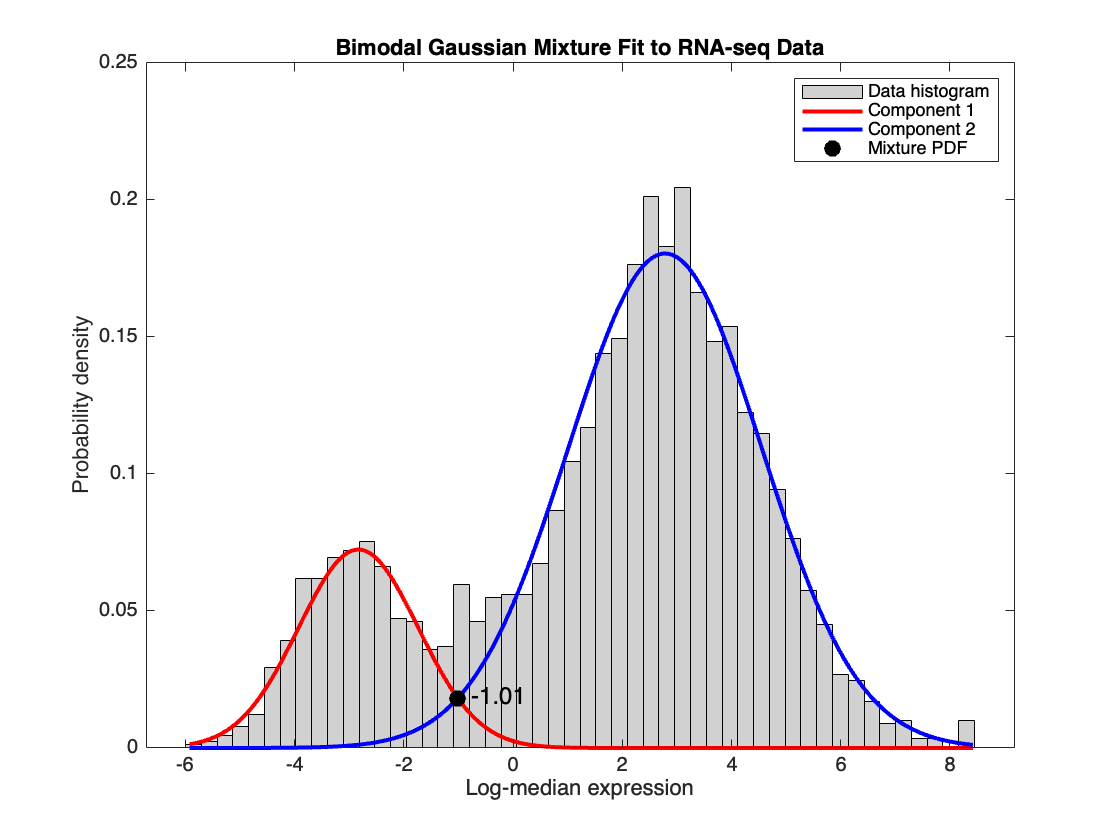

controlThreshold =          -1.01346552050482


function [intersection_x] = fit_rnaseq_dist(compiled_data, recon_genes_list)
    % Filter expression data for Recon3D genes only
    compiled_genes = string(compiled_data.GeneID);
    keep_idx = ismember(compiled_genes, recon_genes_list);
    compiled_data_filtered = compiled_data(keep_idx, :);

    % Compute median expression across samples
    data_median = median(compiled_data_filtered, 2);

    % Filter for genes with nonzero expression and apply log
    keep_idx = data_median{:,1} > 0;
    data_median = data_median(keep_idx, :);
    data = log(data_median);

    % Plot a histogram of the expression data
    X = data{:,1};
    figure;
    histogram(X, 50, 'Normalization', 'pdf', 'FaceColor', [0.7 0.7 0.7]);
    hold on;

    % Gaussian Mixture Model (GMM) Fitting
    n_components = 2;
    % 'fitgmdist' function from Statistics and Machine Learning Toolbox
    gmm = fitgmdist(X, n_components, 'CovarianceType', 'full', 'RegularizationValue', 0.001, 'Replicates', 10); % Added regularization for stability
    
    means = gmm.mu';
    stds = sqrt(squeeze(gmm.Sigma));
    weights = gmm.ComponentProportion;
    
    % Define functions for both peaks in the bimodal distribution
    component_1 = @(x) weights(1) * normpdf(x, means(1), stds(1));
    component_2 = @(x) weights(2) * normpdf(x, means(2), stds(2));

    % Define values for plotting PDFs
    x_values = linspace(min(X), max(X), 1000);
    pdf1 = component_1(x_values);
    pdf2 = component_2(x_values);
    plot(x_values, pdf1, 'r', 'LineWidth', 2);
    plot(x_values, pdf2, 'b', 'LineWidth', 2);

    % Define the difference function: f(x) = PDF1(x) - PDF2(x)
    pdf_difference = @(x) component_1(x) - component_2(x);
    
    % Find the Intersection Point (Root Finding)
    % Sort means to define the bracket for root finding
    sorted_means = sort(means);
    bracket_min = sorted_means(1);
    bracket_max = sorted_means(2);
    
    % Use fzero for root finding - where does the function to change sign over the interval
    intersection_x = fzero(pdf_difference, [bracket_min, bracket_max]);
    fprintf('The calculated intersection point (intersection_x) is: %.4f\n', intersection_x);

    % Mark the intersection point (threshold) if calculated
    if exist('intersection_x', 'var')
        y_intersect = weights(1)*normpdf(intersection_x, means(1), stds(1));
        plot(intersection_x, y_intersect, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
        text(intersection_x, y_intersect, sprintf('  %.2f', intersection_x), 'FontSize', 12);
    end
    
    xlabel('Log-median expression');
    ylabel('Probability density');
    title('Bimodal Gaussian Mixture Fit to RNA-seq Data');
    legend('Data histogram', 'Component 1', 'Component 2', 'Mixture PDF', 'Intersection');
    hold off;
end

% Load list of Recon3D gene IDs
recon_table = readtable([DATA_DIR filesep 'recon3D_full_genes.csv'], 'ReadVariableNames', true);
recon_genes_list = string(recon_table{:,1});

controlThreshold = fit_rnaseq_dist(controlTpms, recon_genes_list)

The calculated intersection point (intersection_x) is: -1.0284


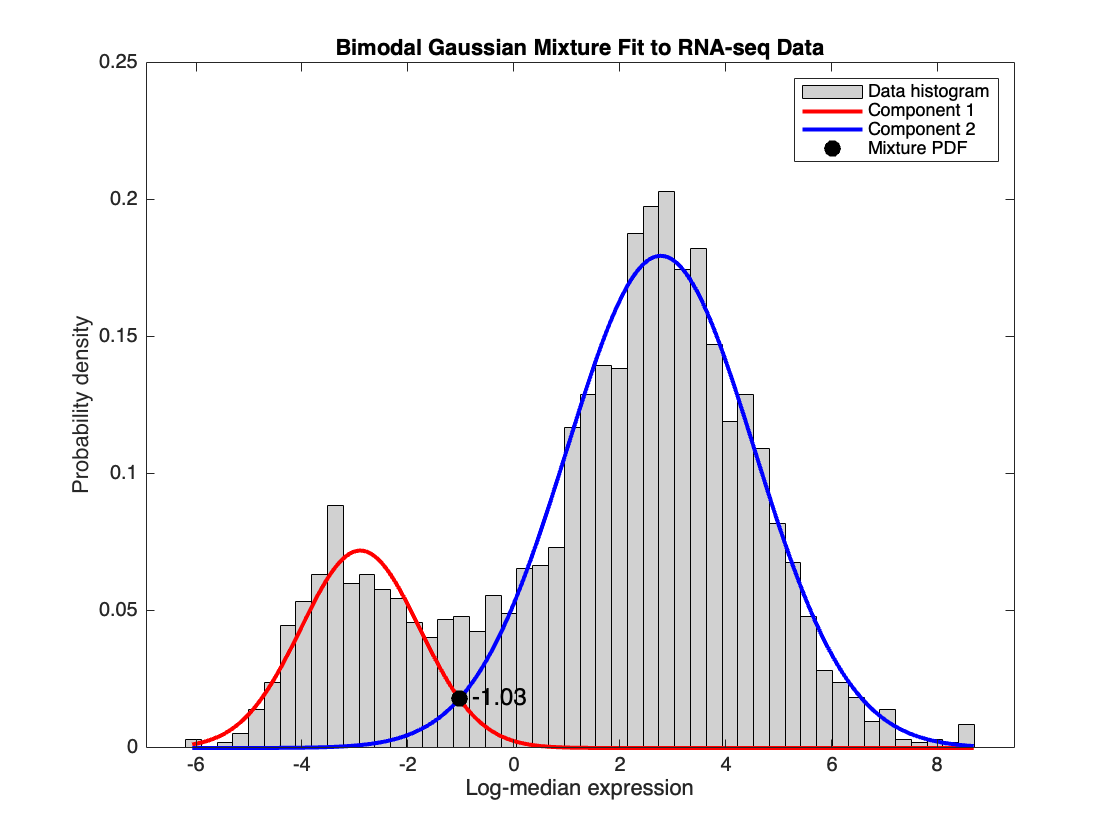

treatedThreshold =          -1.02838434208999


treatedThreshold = fit_rnaseq_dist(treatedTpms, recon_genes_list)

### 4. Run XomicsToModel

We will generate context-specific models for the TNBC MDA-MB-231 cell line. See the [XomicsToModel tutorial](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_XomicsToModel.html) for additional details on data and parameter inputs.

function [model] = run_xomics_pipeline(exprData, recon, threshold, mediaData, outputDir, modelName)
    % Extract gene names and TPMs from the expression matrix
    % Assumes first column contains entrez gene IDs and second column
    % onwards contains expression TPMs
    geneNames = cellstr(string(exprData{:, 1}));
    numData = table2array(exprData(:, 2:end));

    % Strip version suffixes from Recon gene IDs
    reconGenes_floor = regexprep(recon.genes, '\.\d+$', '');
    reconGenes_floor = unique(reconGenes_floor);

    genes = {};
    expVal = [];
    % Map expression to recon genes
    for i = 1:length(reconGenes_floor)
        g = reconGenes_floor{i};

        I = find(strcmp(geneNames, g));

        if ~isempty(I)
            gExp = numData(I, :);
            if size(gExp,1) > 1
                gExp = mean(gExp,1);
            end
            genes{end+1} = g;
            expVal(end+1,:) = gExp;
        else
            fprintf('Note: gene %s not found in expression data.\n', g);
        end
    end

    % Set data for Xomics
    specificData = {};
    specificData.transcriptomicData.genes = genes;
    specificData.transcriptomicData.expVal = expVal;
    specificData.mediaData = mediaData;
    specificData.essentialAA = cell2table({
        'EX_his_L[e]';'EX_ile_L[e]';'EX_leu_L[e]';'EX_lys_L[e]';'EX_met_L[e]';'EX_phe_L[e]';'EX_thr_L[e]';'EX_trp_L[e]';'EX_val_L[e]' 
    }, 'VariableNames', {'rxns'});
    specificData.activeReactions = {};
    specificData.activeGenes = {};
    specificData.inactiveGenes = {};

    % Set params for Xomics
    param = struct();
    param.printLevel = 1;
    param.debug = true;
    param.workingDirectory = outputDir;

    feasTol = getCobraSolverParams('LP','feasTol');
    param.diaryFilename = sprintf('%s/%s_diary.txt', outputDir, modelName);
    param.curationOverOmics = true;
    param.setObjective = 'biomass_reaction';
    param.closeUptakes = true;
    param.closeIons = true;
    param.nonCoreSinksDemands = 'closeAll';
    param.boundPrecisionLimit = feasTol * 10;
    param.thermoFluxEpsilon = feasTol * 10;
    param.growthMediaBeforeReactionRemoval = true;
    param.metabolomicsBeforeModelExtractions = true;
    param.fluxEpsilon = feasTol * 10;
    param.steadyStateRelax = 1;
    % Setting this to true causes biomass_reaction to be pruned during
    % createTissueSpecificModel step - may result from sparse expression
    % data
    param.inactiveGenesTranscriptomics = false; 
    param.transcriptomicThreshold = threshold;

    fprintf('Running XomicsToModel for %s ...\n', modelName);
    [model, ~] = XomicsToModel(recon, specificData, param);
    outFile = sprintf('%s/%s.mat', outputDir, modelName);
    writeCbModel(model, outFile);
end

Generate model for normoxic samples.

Note: gene 0 not found in expression data.
Note: gene 100507855 not found in expression data.
Note: gene 201288 not found in expression data.
Note: gene 644378 not found in expression data.
Note: gene 645740 not found in expression data.
Note: gene 8041 not found in expression data.
Note: gene 8781 not found in expression data.
Running XomicsToModel for normoxic ...
XomicsToModel run, beginning at:10-Dec-2025 16:54:05
--------------------------------------------------------------
 
XomicsToModel input specificData:
 
    transcriptomicData: [1×1 struct]
             mediaData: [44×2 table]
           essentialAA: [9×1 table]
       activeReactions: {}
           activeGenes: {}
         inactiveGenes: {}
           rxns2remove: []

XomicsToModel input param:
 
                            printLevel: 1
                                 debug: 1
                      workingDirectory: '/Users/dluong/Documents/ctx/models/tutorial_gse127507'
                         diaryFilename: '/Users/d

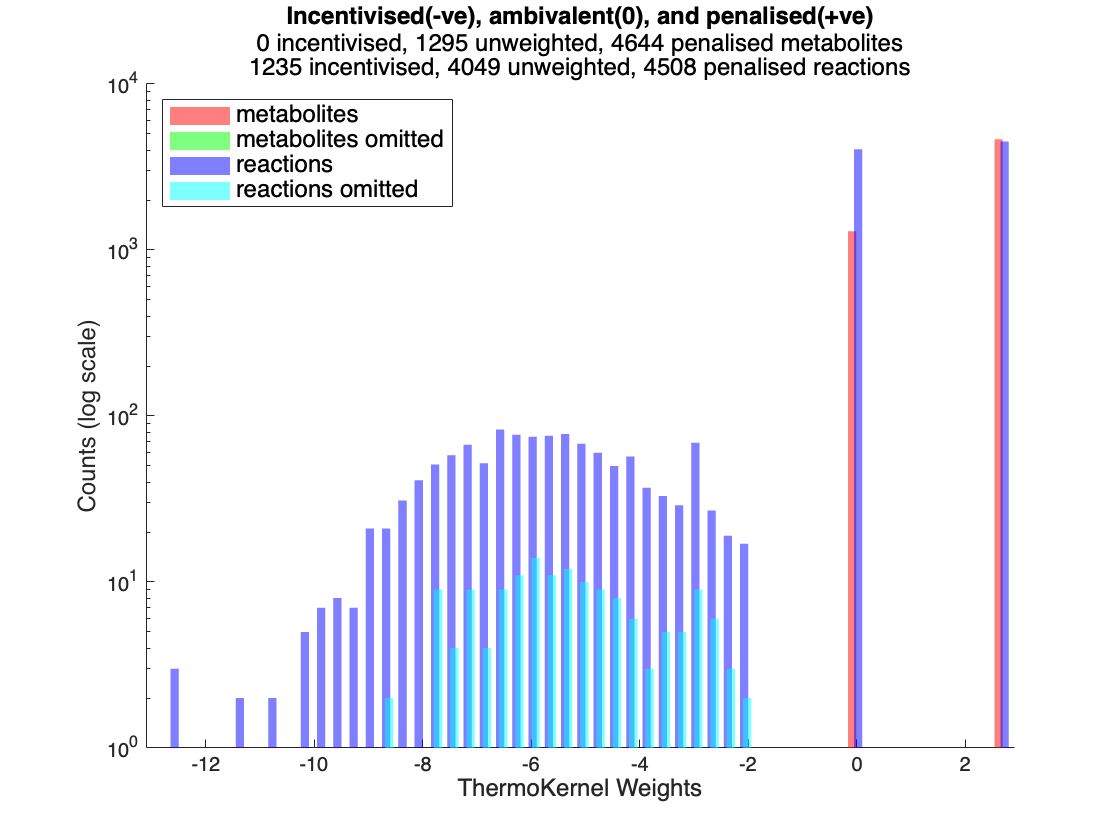

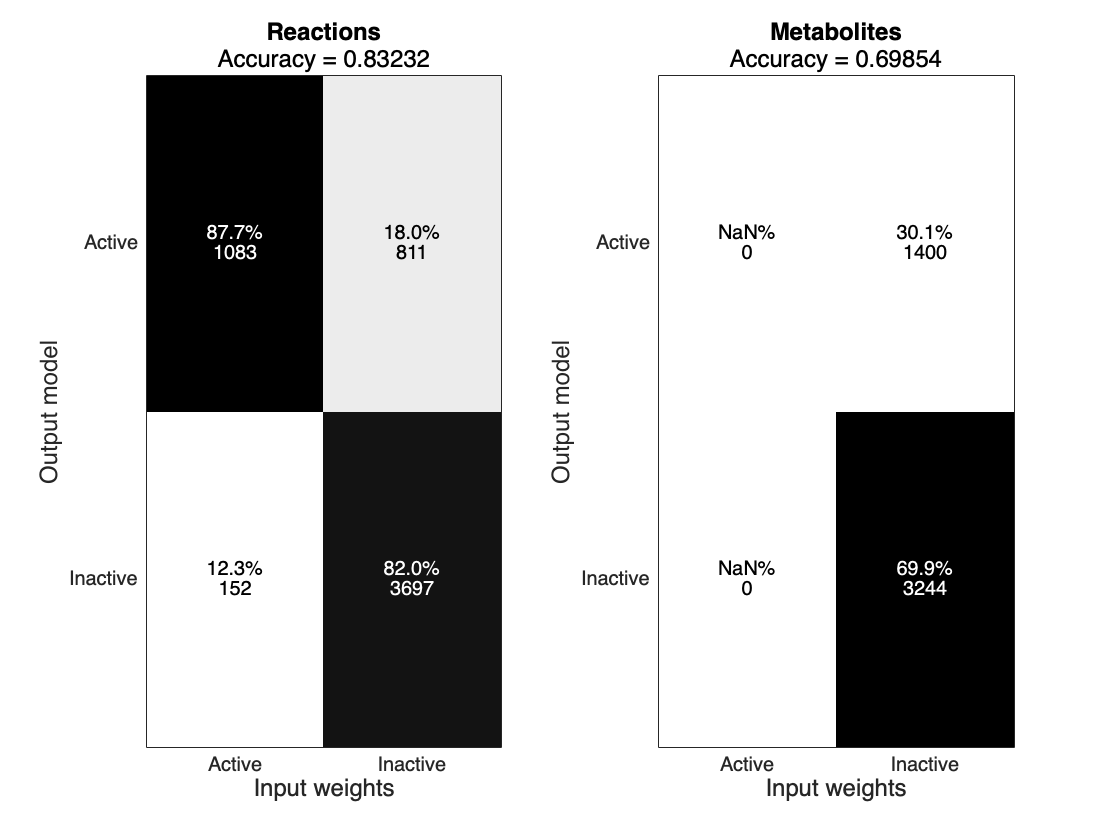

4439 deleted non-core metabolites,  corresponding to removal by createTissueSpecificModel.
0 deleted core metabolites,  corresponding to removal by createTissueSpecificModel.
7224 deleted non-core reactions,  corresponding to removal by createTissueSpecificModel.
4 deleted core reactions,  corresponding to removal by createTissueSpecificModel.
    Reverse_Reaction, 0 bound                Name                   lb        ub        equation    
    _________________________    ____________________________    _________    __    ________________

          {'EX_fe3[e]'}          {'Exchange of Iron (Fe3+) '}    -1.01e-05    0     {'fe3[e]  <=> '}

    Reversible_Reaction                  Name                        lb          ub          equation</

controlName='normoxic';
mediaData = readtable([DATA_DIR filesep 'MDA-MB-231_Normoxia_exchanges.csv']);
controlModel = run_xomics_pipeline(controlTpms, recon, controlThreshold, mediaData, outputModelDir, controlName);

Generate model for hypoxic samples.

Note: gene 0 not found in expression data.
Note: gene 100507855 not found in expression data.
Note: gene 201288 not found in expression data.
Note: gene 644378 not found in expression data.
Note: gene 645740 not found in expression data.
Note: gene 8041 not found in expression data.
Note: gene 8781 not found in expression data.
Running XomicsToModel for hypoxic ...
XomicsToModel run, beginning at:10-Dec-2025 17:52:39
--------------------------------------------------------------
 
XomicsToModel input specificData:
 
    transcriptomicData: [1×1 struct]
             mediaData: [44×2 table]
           essentialAA: [9×1 table]
       activeReactions: {}
           activeGenes: {}
         inactiveGenes: {}
           rxns2remove: []

XomicsToModel input param:
 
                            printLevel: 1
                                 debug: 1
                      workingDirectory: '/Users/dluong/Documents/ctx/models/tutorial_gse127507'
                         diaryFilename: '/Users/dl

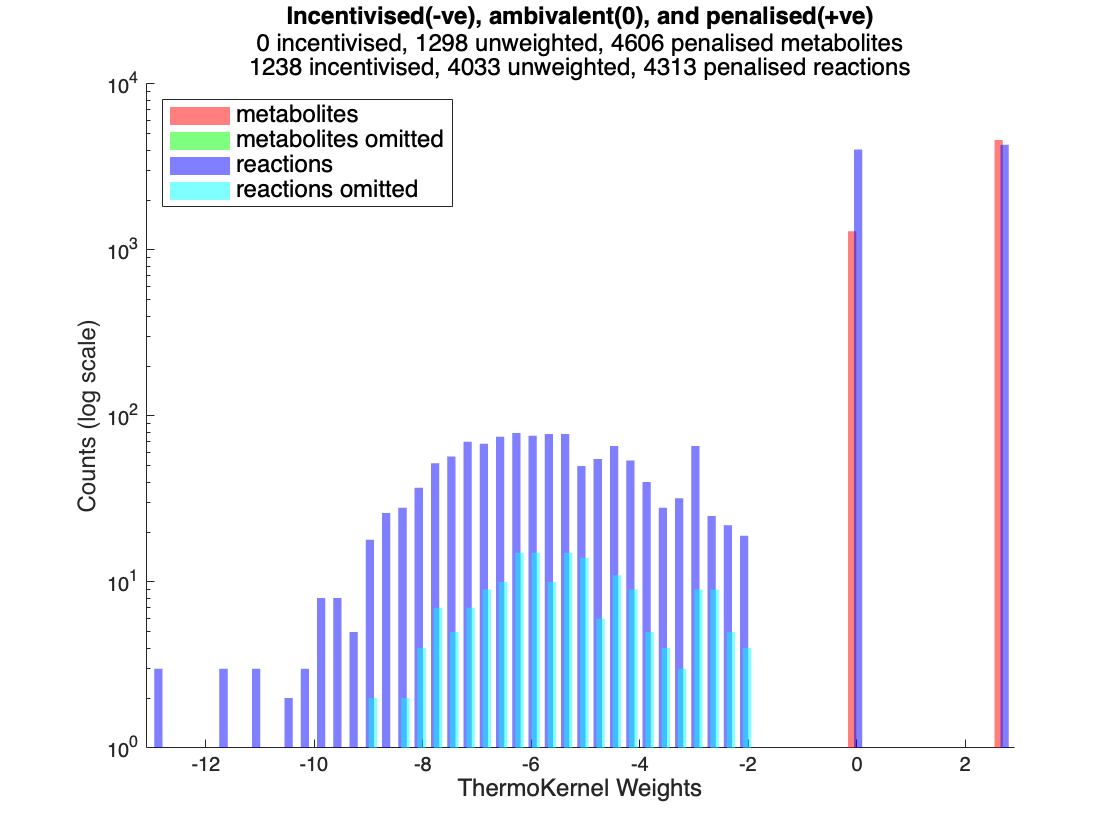

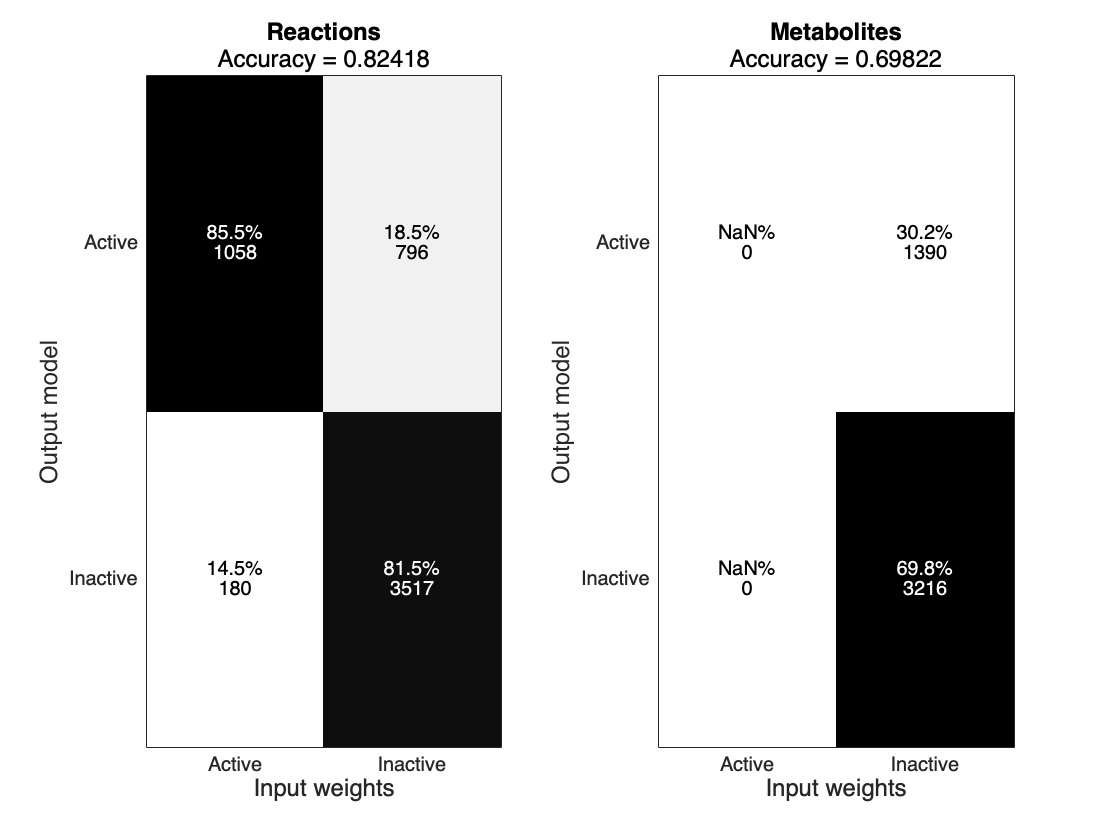

4414 deleted non-core metabolites,  corresponding to removal by createTissueSpecificModel.
0 deleted core metabolites,  corresponding to removal by createTissueSpecificModel.
7043 deleted non-core reactions,  corresponding to removal by createTissueSpecificModel.
5 deleted core reactions,  corresponding to removal by createTissueSpecificModel.
    Reverse_Reaction, 0 bound                Name                   lb        ub        equation    
    _________________________    ____________________________    _________    __    ________________

          {'EX_fe3[e]'}          {'Exchange of Iron (Fe3+) '}    -1.01e-05    0     {'fe3[e]  <=> '}

    Reversible_Reaction                  Name                        lb          ub          equation</

treatedName='hypoxic';
mediaData = readtable([DATA_DIR filesep 'MDA-MB-231_Hypoxia_exchanges.csv']);
treatedModel = run_xomics_pipeline(treatedTpms, recon, treatedThreshold, mediaData, outputModelDir, treatedName);

### 5. Flux sampling

Uniform sampling of the flux space provides a generalized characterization of the biochemical network and may be used to investigate flux capacities and variability across feasible flux states of biochemical networks.

The traditional MCMC (Markov Chain Monte Carlo) Hit-and-Run (HR) sampler struggles with sufficiently sampling irregularly shaped solution spaces. The Artificial Centering Hit-and-Run (ACHR) sampler addresses this issue by computing an artificial center point to guide direction selection for each sampling iteration. However, computation of the artificial center depends on all prior samples, making ACHR non-Markovian and not guaranteed convergence on the stationary distribution.${\;}^5$ This tutorial uses the Coordinate-Hit-and-Run with Rounding (CHRR) sampler, which first rounds the polytope to improve MCMC sampling efficiency.${\;}^6$

Briefly, CHRR is called using `sampleCbModel,` where the thinning factor / sampling density is specified using `nStepsPerPoint` and the number of samples is specified by `nPointsReturned`. For additional details about sampling, see tutorial on [uniform sampling of genome-scale models](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_uniformSampling_genomeScale.html).  

function [roundedPolytope, outputTable] = sampleModel(model, outputFile, prevRoundPolytope)
    
    % Round if roundedPolytope not provided
    toRound = 0;
    if nargin < 3 || isempty(prevRoundPolytope)
        toRound = 1; 
    end

    % Rule of thumb = set to 8*n
    % Reducing this reduces runtime but risks non-convergence
    options.nStepsPerPoint = 8*size(model.S, 2);
    sprintf('Using nStepsPerPoint %d\n', options.nStepsPerPoint)
    options.nPointsReturned = 1000;
    options.toRound = toRound;
    options.optPercentage = 85; % desired minimum biomass for all samples
    options.useFastFVA = false;
    if toRound == 1
        [roundedPolytope, samples] = sampleCbModel(model, [], 'CHRR', options);
    else
        disp('Using previously generated rounded polytope.\n')
        [~, samples] = sampleCbModel(model, [], 'CHRR', options, prevRoundPolytope);
        % Setting output
        roundedPolytope = prevRoundPolytope;s
    end

    reactionIDs = model.rxns;
    outputTable = [reactionIDs, num2cell(samples)];
    writecell(outputTable, outputFile);
    fprintf('Samples saved to %s\n', outputFile);
end

if ~exist(outputSampleDir,'dir')
    mkdir(outputSampleDir);
end

% Load media exchange information

Run flux sampling for control normoxic model.

% NOTE: if running more than once, add controlPolytope as an additional
% parameter to skip the rounding step
tic;
controlModel = readCbModel([outputModelDir filesep 'normoxic.mat']);

Each model.subSystems{x} is a character array, and this format is retained.


controlMediaData = readtable([DATA_DIR filesep 'MDA-MB-231_Normoxia_exchanges.csv']);
for i = 1:height(controlMediaData)
    rxnID = controlMediaData{i,1}{1}; 
    fluxVal = controlMediaData{i,2};  % Relax media constraints 
    rxnIndex = find(strcmp(controlModel.rxns, rxnID));
    controlModel.lb(rxnIndex) = fluxVal; 
    % Set upper bound of oxygen exchange to 0
    if strcmp(rxnID, 'EX_o2[e]')
        controlModel.ub(rxnIndex) = 0;
    end
end
[controlPolytope, controlSamples] = sampleModel(controlModel, [outputSampleDir filesep 'normoxic_samples.csv']);

ans =     'Using nStepsPerPoint 20512
     '


Checking for width 0 facets...
Currently (P.A, P.b) are in 2564 dimensions
Checking for width 0 facets...
Found 2 degenerate reactions, adding them to the equality subspace.


Now in 1194 dimensions after restricting
Removed 5125 zero rows
Preconditioning A with gmscale
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=0.0e+00, longest axis=1.3e-01, shortest axis=1.0e-02, x0 dist to bdry=6.0e-03, time=1.8e+01 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=Inf, longest axis=8.1e+01, shortest axis=2.1e+00, x0 dist to bdry=1.3e+00, time=6.3e+02 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=Inf, longest axis=5.9e+01, shortest axis=9.4e-01, x0 dist to bdry=1.1e+00, time=3.8e+02 seconds
  Converged!
Iteration 4: reg=1.0e-07, ellipsoid vol=Inf, longest axis=3.6e+03, shortest axis=1.2e+00, x0 dist to bdry=1.2e+00, time=3.0e+02 seconds
Maximum volume ellipsoid found, and the origin is inside the transformed polytope.
Generating samples...
Samples saved to /Users/dluong/Documents/ctx/samples/tutorial_gse127507/normoxic_samples.csv


toc;

Elapsed time is 929.765665 seconds.


Run flux sampling for treated hypoxic model.

% NOTE: if running more than once, add treatedPolytope as an additional
% parameter to skip the rounding step
tic;
treatedModel=readCbModel([outputModelDir filesep 'hypoxic.mat']);

Each model.subSystems{x} is a character array, and this format is retained.


hypoxicMediaData = readtable([DATA_DIR filesep 'MDA-MB-231_Hypoxia_exchanges.csv']);
for i = 1:height(hypoxicMediaData)
    rxnID = hypoxicMediaData{i,1}{1}; 
    fluxVal = hypoxicMediaData{i,2};  % Relax media constraints 
    rxnIndex = find(strcmp(treatedModel.rxns, rxnID));
    treatedModel.lb(rxnIndex) = fluxVal; 
    % Set upper bound of oxygen exchange to 0
    if strcmp(rxnID, 'EX_o2[e]')
        controlModel.ub(rxnIndex) = 0;
    end
end
[treatedPolytope, treatedSamples] = sampleModel(treatedModel, [outputSampleDir filesep 'hypoxic_samples.csv']);

ans =     'Using nStepsPerPoint 20288
     '


Checking for width 0 facets...
Currently (P.A, P.b) are in 2536 dimensions
Checking for width 0 facets...
Found 0 degenerate reactions, adding them to the equality subspace.


Now in 1201 dimensions after restricting
Removed 5073 zero rows
Preconditioning A with gmscale
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=0.0e+00, longest axis=2.3e-01, shortest axis=6.9e-03, x0 dist to bdry=6.8e-03, time=1.7e+01 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=Inf, longest axis=1.6e+01, shortest axis=1.1e+00, x0 dist to bdry=1.3e+00, time=2.1e+01 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=Inf, longest axis=1.2e+01, shortest axis=8.6e-01, x0 dist to bdry=1.2e+00, time=2.1e+01 seconds
Stopped making progress, stopping and restarting.
Iteration 4: reg=1.0e-07, ellipsoid vol=Inf, longest axis=1.8e+03, shortest axis=1.2e+00, x0 dist to bdry=1.2e+00, time=8.3e+01 seconds
Stopped making progress, stopping and restarting.
Iteration 5: reg=1.0e-08, ellipsoid vol=3.1e+222, longest axis=6.2e+00, shortest axis=6.4e-01, x0 dist to bdry=1.0e+00, time=4.2e+01 seconds
Stopped making progress, stopping and restarting.
Iteration 6: reg=1.0e-09, ellipsoid vol=2.2e+234, long

toc;

Elapsed time is 719.753857 seconds.


### 6. Sampling convergence

MCMC-based flux sampling approximates the true flux space of the biochemical network. The accuracy of this approximation depends on whether the sampling chain has converged on the true underlying flux distributions.

The primary visual tools for evaluating the convergence of the sampling chain are trace plots and autocorrelation plots. 

Trace plots show the sampled flux values for a specific reaction over the course of the sampling chain. Any visible non-randomness in the trace plot, such as long-term drifts, trends, or distinct plateaus, indicates that the sampling chain has not converged. A converged chain should resemble a stable random walk around the mean. 

Autocorrelation plots show the correlation of a sample with previous samples in the chain. High autocorrelation between samples indicates that successive samples are not independent of one another. The autocorrelation of a converged chain should drop off quickly towards zero, indicating that the samples are independent of one another.

These methods are implemented in MATLAB here for convenenience, but the R coda package is more frequently used to assess MCMC convergence and includes additional statistical tests for convergence.

function assessConvergence(model, samples, rxnName)
    fluxData=table2array(samples(:, 2:end));
    chain = fluxData'; 

    % Find the index of the target 'rxnName' reaction
    rxnIdx=find(strcmp(model.rxns, rxnName));
    if isempty(rxnIdx)
        error('Reaction "%s" not found in model.rxns', rxnName);
    end
    
    % Extract the chain for the specific reaction
    rxnChain = chain(:, rxnIdx);
    
    % Plot the trace
    figure;
    subplot(2,1,1);
    plot(rxnChain);
    xlabel('Iteration');
    ylabel('Flux');
    title(['Trace plot for reaction: ' rxnName]);

    % Plot autocorrelation
    subplot(2,1,2);
    autocorr(rxnChain);
    title(['Autocorrelation for reaction: ' rxnName]);
end

controlModel = readCbModel([outputModelDir filesep 'normoxic.mat']);

Each model.subSystems{x} is a character array, and this format is retained.


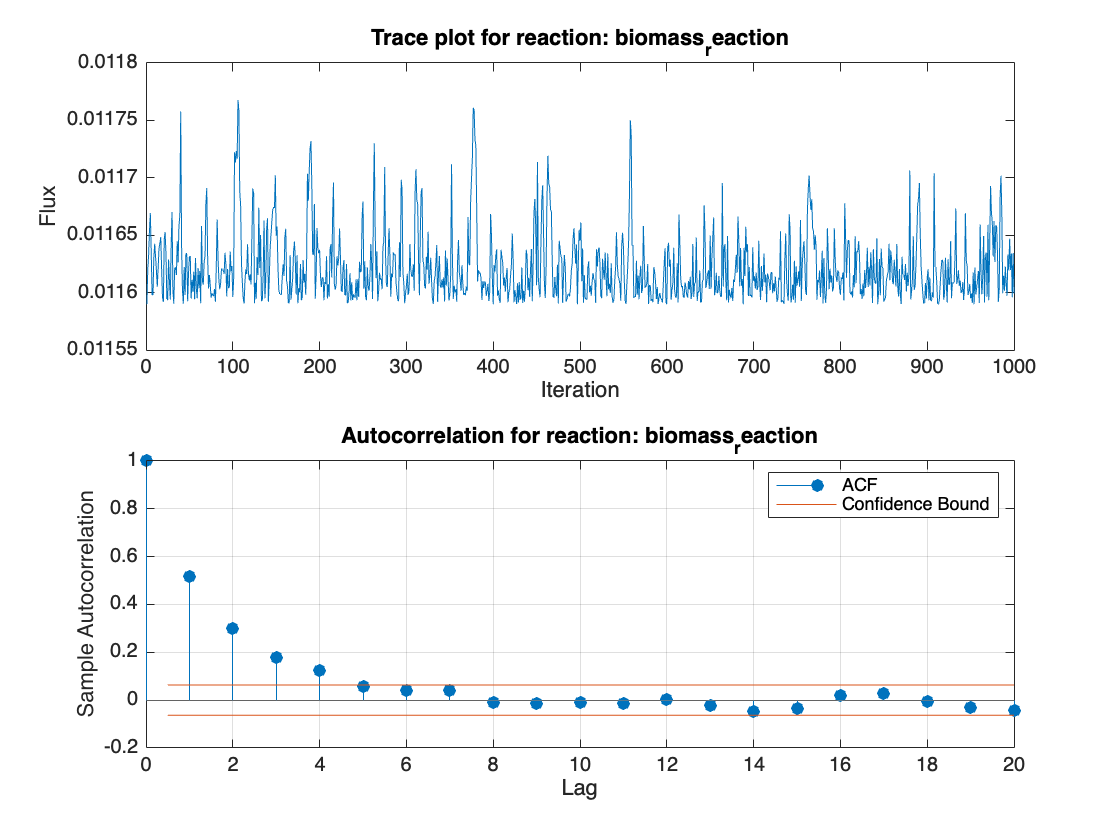

controlSamples=readtable([outputSampleDir filesep 'normoxic_samples.csv']);
assessConvergence(controlModel, controlSamples, 'biomass_reaction')

treatedModel = readCbModel([outputModelDir filesep 'hypoxic.mat']);

Each model.subSystems{x} is a character array, and this format is retained.


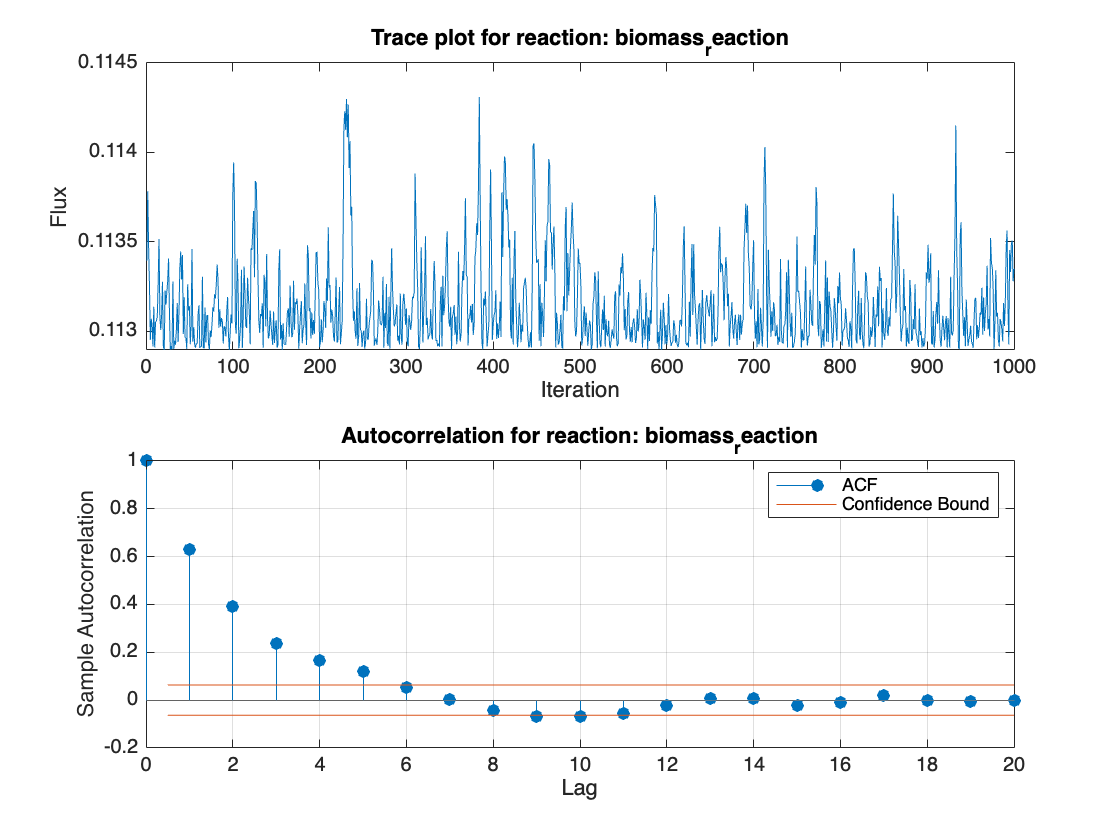

treatedSamples=readtable([outputSampleDir filesep 'hypoxic_samples.csv']);
assessConvergence(treatedModel, treatedSamples, 'biomass_reaction')

### 7. Differential Flux Analysis

Differential flux analysis (DFA) uses statistical methods to identify reactions and pathways with significant differences. For each reaction, the Mann–Whitney U test is applied to compare the medians of flux samples, and resulting p-values are corrected for multiple testing using FDR. Hypergeometric enrichment analysis is then performed to determine which metabolic subsystems and compartments are overrepresented among the differential reactions.${\;}^7$

This is more commonly performed in Python (scipy), but is implemented in MATLAB here for convenience.

controlSamples = readtable([outputSampleDir filesep 'normoxic_samples.csv'], 'ReadRowNames', true);
treatedSamples = readtable([outputSampleDir filesep 'hypoxic_samples.csv'], 'ReadRowNames', true);

% Filter for reactions shared by both models
commonReactions = intersect(controlSamples.Properties.RowNames,  treatedSamples.Properties.RowNames, 'stable');
controlFiltered = controlSamples(commonReactions, :);
treatedFiltered = treatedSamples(commonReactions, :);
controlMatrix = table2array(controlFiltered);
treatedMatrix = table2array(treatedFiltered);

% Define output variables
numReactions = length(commonReactions);
pvals = zeros(numReactions, 1);
controlMedians = zeros(numReactions, 1);
treatedMedians = zeros(numReactions, 1);
ratioOfDifferences = zeros(numReactions, 1);

% Perform Mann-Whitney U tests
for i = 1:numReactions
    % Extract the flux values for the current reaction
    lowFluxes = controlMatrix(i, :);
    highFluxes = treatedMatrix(i, :);
    
    [p, h, stats] = ranksum(lowFluxes, highFluxes);
    pvals(i) = p;
    
    % Calculate medians
    controlMedian = median(lowFluxes);
    treatedMedian = median(highFluxes);

    controlMedians(i) = controlMedian;
    treatedMedians(i) = treatedMedian;

    % Compute flux changes
    if abs(controlMedian) + abs(treatedMedian) ~= 0
        fc = (treatedMedian - controlMedian) / (abs(controlMedian) + abs(treatedMedian));
    else
        fc = 0; 
    end
    
    ratioOfDifferences(i) = fc;
end

% Perform Benjamini-Hochberg p-value correction
adjustedPValues = mafdr(pvals, 'BHFDR', true);

alpha = 0.05;
fcThreshold = 0.82;
statThreshold = (adjustedPValues < alpha);
fluxChangeThreshold = (abs(ratioOfDifferences) > fcThreshold);
isSignificant = statThreshold & fluxChangeThreshold;
sigCount = sum(isSignificant);

disp(['Found ', num2str(sigCount), ' significant fluxes that met fold-change threshold.']);

Found 399 significant fluxes that met fold-change threshold.


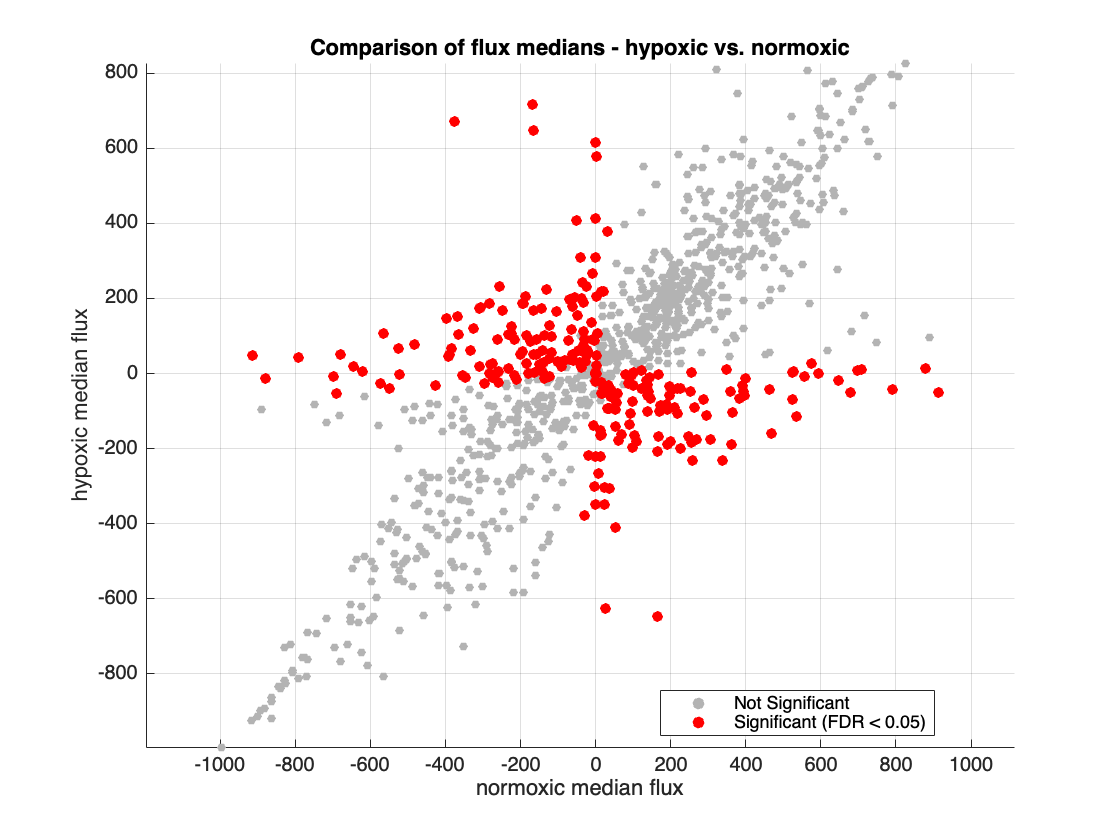

% Generate dot plot of flux medians, colored by significance
figure;
hold on;
title('Comparison of flux medians - hypoxic vs. normoxic');
xlabel('normoxic median flux');
ylabel('hypoxic median flux');

% Plot non-significant features in gray
scatter(controlMedians(~isSignificant), treatedMedians(~isSignificant), 20, [0.7 0.7 0.7], 'filled', 'DisplayName', 'Not Significant');

% Plot significant features in red
scatter(controlMedians(isSignificant), treatedMedians(isSignificant), 30, 'r', 'filled', 'DisplayName', ['Significant (FDR < ', num2str(alpha), ')']);

% Add the line of identity (y = x)
maxVal = max([controlMedians; treatedMedians]);
minVal = min([controlMedians; treatedMedians]);

axis equal; % Ensure the x and y axes have the same scale
grid on;
legend('Location', 'best');
hold off;

% Plot density function for specific reactions of interest
function plotKDEForReaction(controlFiltered, treatedFiltered, commonReactions, reactionName)
    % Find the index of the target reaction in the reaction list
    idx = find(strcmp(commonReactions, reactionName), 1);
    if isempty(idx)
        error(['The reaction ''', reactionName, ''' was not found in the common set of reactions.']);
    end
    
    % Get flux samples for target reaction
    controlFluxes = table2array(controlFiltered(idx, :));
    treatedFluxes = table2array(treatedFiltered(idx, :));
    
    figure;
    hold on;
    title(['Kernel Density Estimation (KDE) Plot for ', reactionName]);
    xlabel(['Flux Value for ', reactionName]);
    ylabel('Probability Density');
    
    % Plot density functions for low and high fluxes for this reaction
    [f_control, xi_control] = ksdensity(controlFluxes);
    plot(xi_control, f_control, 'b', 'LineWidth', 2, 'DisplayName', 'normoxic');
    control_median = median(controlFluxes);
    plot([control_median, control_median], ylim, 'b--', 'LineWidth', 1, 'HandleVisibility', 'off'); 
    
    [f_treated, xi_treated] = ksdensity(treatedFluxes);
    plot(xi_treated, f_treated, 'r', 'LineWidth', 2, 'DisplayName', 'hypoxic');
    treated_median = median(treatedFluxes);
    plot([treated_median, treated_median], ylim, 'r--', 'LineWidth', 1, 'HandleVisibility', 'off'); 
    
    % Set x-axis limits
    max_x = max([xi_control, xi_treated]);
    min_x = min([xi_control, xi_treated]);
    xlim([min_x, max_x]);
    
    legend('Location', 'best');
    hold off;

    disp(['normoxic median: ', num2str(control_median, '%.3f'), ', hypoxic median: ', num2str(treated_median, '%.3f')]);
end


Biomass is reduced in the hypoxic model, indicating that under the assumptions of the model (steady state), proliferation of MDA-MB-231 cells is blunted under hypoxic conditions. 

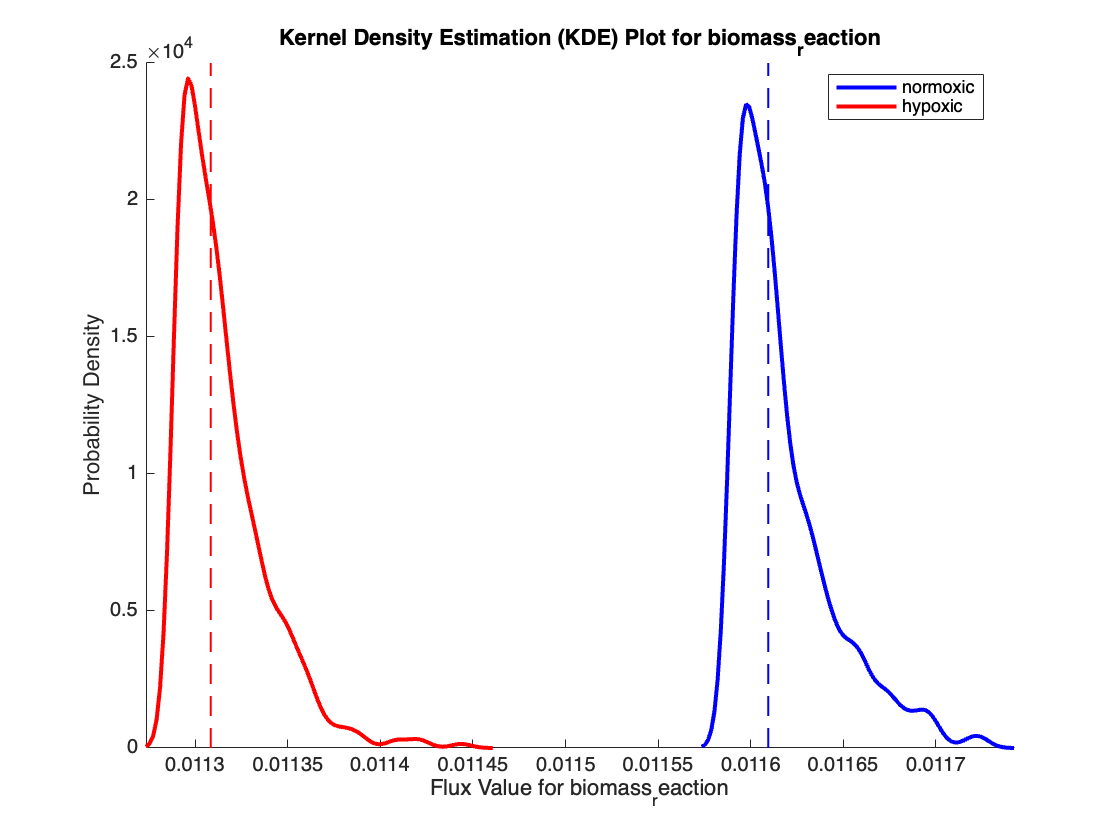

normoxic median: 0.012, hypoxic median: 0.011


plotKDEForReaction(controlFiltered, treatedFiltered, commonReactions, 'biomass_reaction')

Confirms constraints on oxygen uptake in normoxic vs. hypoxic models.

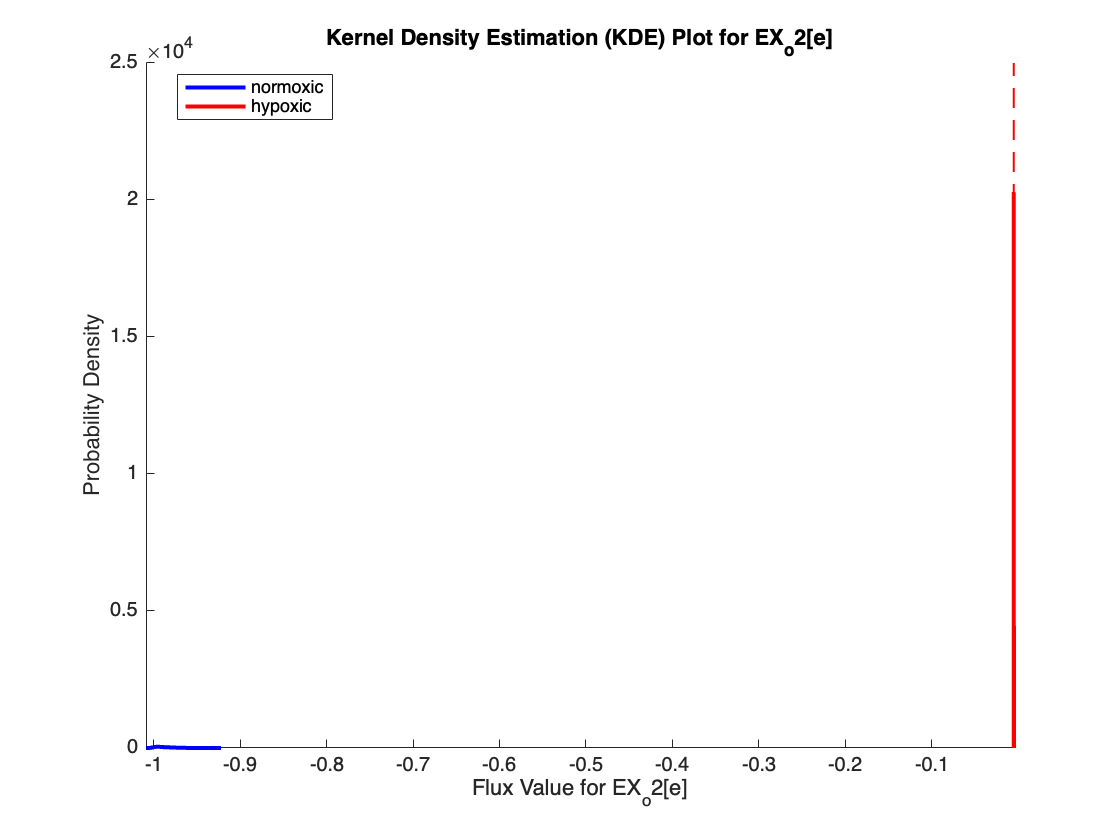

normoxic median: -0.989, hypoxic median: -0.005


plotKDEForReaction(controlFiltered, treatedFiltered, commonReactions, 'EX_o2[e]')

Hypoxic models exhibit reduced energy generation via oxidative phosphorylation.

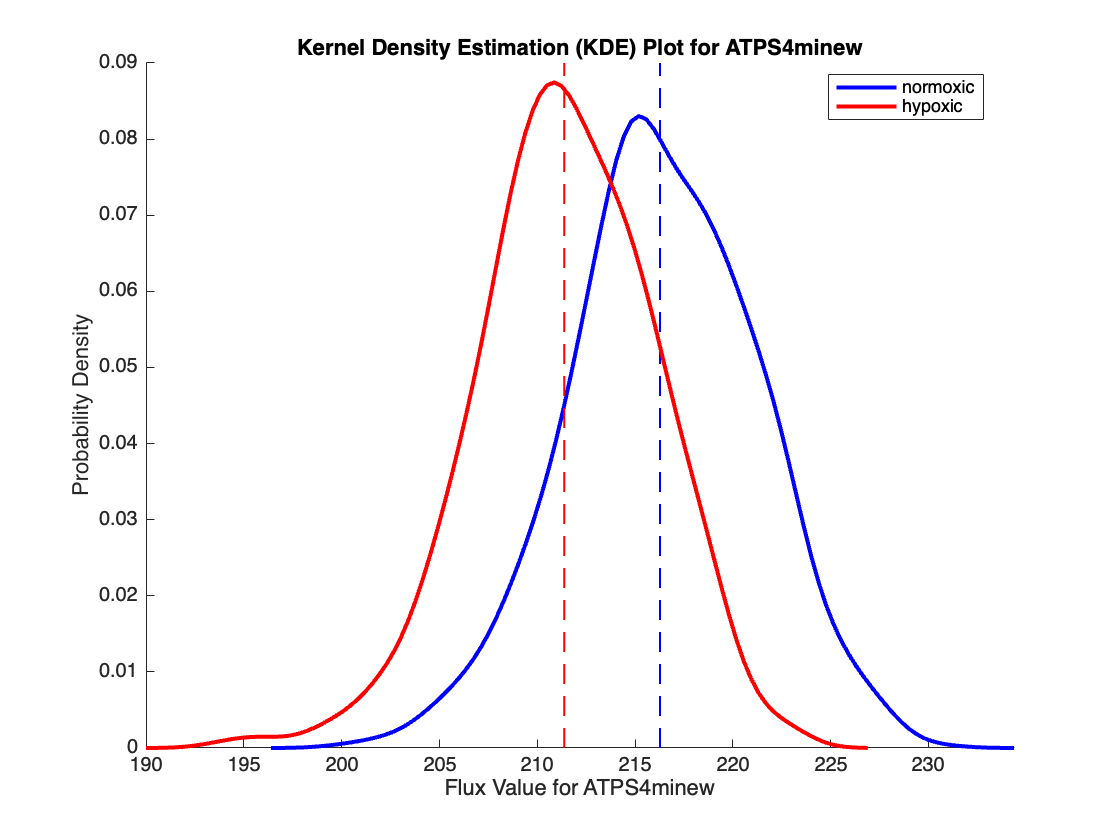

normoxic median: 216.277, hypoxic median: 211.384


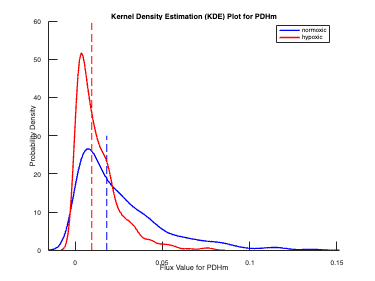

normoxic median: 0.018, hypoxic median: 0.010


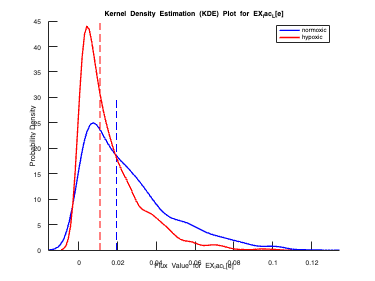

normoxic median: 0.019, hypoxic median: 0.011


plotKDEForReaction(controlFiltered, treatedFiltered, commonReactions, 'ATPS4minew')

## **TIMING**

Steps 1-3: 1 min

Step 4: 2-3 hours

Step 5: 1-2 hours

Step 6+7: runtime ~2-3 minutes, interpretation ~hours

## TROUBLESHOOTING

**General Issue:** Type or format errors during XomicsToModel

**Possible Reason: **XomicsToModel requires inputs to be formatted in specific ways. Failure to do so will result in errors.

**Solution: **double check that format and column names of bibliomic, transcriptomic, and media data files match that of example inputs.

**Issue #1: **Biomass (reaction or maintenance) is pruned from the model by XomicsToModel

**Possible Reason: **Sparse expression data may lead to pruning of reactions essential for flux consistency during XomicsToModel contextualization. 

**Solution: **Set inactiveGenesTranscriptomics to false to disable strict exclusion of inactive genes.

**Issue #2: **Flux sampling fails with error 'x0 is not interior' during rounding step

**Possible Reason: **Flux space is over-constrained and could not find an interior point within the feasible polytope.

**Solution: **Reduce the optPercentage to relax constraints on the flux space, or relax exchange bounds imposed by mediaData.

**Issue #3: **Flux sampling fails with error **'**model.A must be a sparse double real matrix'.

**Possible Reason: **Stale workspace variable may be silently corrupting model.

**Solution: **Clear workspace and rerun flux sampling section.

## ANTICIPATED RESULTS

Step 7 yields statistical prioritization of downstream reactions and pathways for further testing and validation. In this study, Sesé et al. identified significant transcriptional upregulation of glycolytic, fructose, and mannose metabolism, and oxidation-reduction processes in hypoxia. Thus, it is expected the hypoxic metabolic models of carry differential flux in these metabolic pathways as well as downstream pathways.

## REFERENCES

1. Preciat, G., Wegrzyn, A.B., Thiele, I., Hankemeier, T., and Fleming, R.M.T. (2021). XomicsToModel: Omics data integration and generation of thermodynamically consistent metabolic models. Preprint, [10.1101/2021.11.08.467803](https://doi.org/10.1101/2021.11.08.467803).  

2. Brunk, E., Sahoo, S., Zielinski, D.C., Altunkaya, A., Dräger, A., Mih, N., Gatto, F., Nilsson, A., Preciat Gonzalez, G.A., Aurich, M.K., et al. (2018). Recon3D enables a three-dimensional view of gene variation in human metabolism. Nat Biotechnol *36*, 272–281. [10.1038/nbt.4072](https://doi.org/10.1038/nbt.4072).  

3. Heirendt, L., Arreckx, S., Pfau, T., Mendoza, S.N., Richelle, A., Heinken, A., Haraldsdóttir, H.S., Wachowiak, J., Keating, S.M., Vlasov, V., et al. (2019). Creation and analysis of biochemical constraint-based models using the COBRA Toolbox v.3.0. Nat Protoc *14*, 639–702. [10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).  

4. Sesé, M., Fuentes, P., Esteve-Codina, A., Béjar, E., Thomas, G., and Aasen, T. (2017). Hypoxia-mediated translational activation of ITGB3 in breast cancer cells enhances TGF-β signaling and malignant features in vitro and in vivo. Oncotarget 8(70), 114856–114876. [10.18632/oncotarget.23145](https://doi.org/10.18632/oncotarget.23145).

5. Fallahi, S., Skaug, H.J., and Alendal, G. (2020). A comparison of Monte Carlo sampling methods for metabolic network models. PLOS ONE *15*, e0235393. [10.1371/journal.pone.0235393](https://doi.org/10.1371/journal.pone.0235393). 

6. Haraldsdóttir, H.S., Cousins, B., Thiele, I., Fleming, R.M.T., and Vempala, S. (2017). CHRR: coordinate hit-and-run with rounding for uniform sampling of constraint-based models. Bioinformatics *33*, 1741–1743. [https://doi.org/10.1093/bioinformatics/btx052](https://doi.org/10.1093/bioinformatics/btx052).  

7. Beura, S., Das, A.K., and Ghosh, A. (2024). Protocol for genome-scale differential flux analysis to interrogate metabolic differences from gene expression data. STAR Protocols *5*, 103291. [10.1016/j.xpro.2024.103291](https://doi.org/10.1016/j.xpro.2024.103291). 